%https://se.mathworks.com/help/images/ref/affine2d.transformpointsforward.html
%https://technodocbox.com/3D_Graphics/78643914-Advanced-image-processing-tnm034-optical-music-recognition.html
subplot(1,1,1);

demoFolder = matlabroot + "/toolbox/images/imdata/";
demoImages = dir(fullfile(demoFolder + "*.*"));
demoImages = string({demoImages.name});
%testImage = im2double(rgb2gray(imread(demoFolder + "cameraman.tif")));
testImage = im2double(imread(demoFolder + "cameraman.tif"));


folder = "Images/";
imageFileNames = dir(fullfile(folder+ "im*s.jpg"));
imageFileNames = string({imageFileNames.name});

preview = [];
for i=1:size(imageFileNames, 2)
    disp(imageFileNames(i));
    
    imagePath = folder + imageFileNames(i);
    staffNormalizedWidth = 2048;
    drawDebug_alternatingStaffs = true;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Load image and remove background
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    original = imread(imagePath);
    originalgray = im2double(rgb2gray(original)); 
    [notes, region] = removeBackground(originalgray);   
    notes = notes(region(2):region(4), region(1):region(3));

    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Extract alpha of staff lines and create an enclosing
    % mask for each staff.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    lineSearch_angleLimit = 10;
    lineSearch_angleStep = 1;
    lineSearch_minimumLength = round(size(notes,2)*0.4);
    
    % Expand image, otherwise the structuring element might fail near the corners
    paddingWidth = round(lineSearch_minimumLength*0.2);
    paddingHeight = round(paddingWidth*0.2);
    notes = padarray(notes, [paddingHeight, paddingWidth], 1, 'both');
    
    % Attempt to extract the masks
    staffLinesAlpha = getLinesAlphaByAngle(notes, lineSearch_angleLimit, lineSearch_angleStep, lineSearch_minimumLength);
    staffsMask = imclose(staffLinesAlpha, strel('disk', 16, 4));
    staffsMask = (staffsMask > graythresh(staffsMask));

    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Use mask of staffs to detect perspective transform
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    perspective = estimatePerspectiveTransform(staffsMask);
    perspectiveInverse = invert(perspective);
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Apply perspective correction to image and alpha
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    notes = 1-imwarp(1-notes, perspectiveInverse, 'cubic');
    staffLinesAlpha = imwarp(staffLinesAlpha, perspectiveInverse, 'cubic');
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Recreate staffsmask post-transform. 
    % Also create a new mask which includes notes hanging
    % outside the staff.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    staffsMask = imclose(staffLinesAlpha, strel('disk', 16, 4));
    staffsMask = (staffsMask > graythresh(staffsMask));
    
    notesMask = (notes < graythresh(notes));
    notesMask = or(notesMask, staffsMask);
    notesMask = bwareaopen(notesMask, size(notes,2));
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Use the mask to remove clutter
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    notes = 1-(1-notes).*notesMask;  

    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Split image into a separate segment for each staff
    % based on the masks.
    %
    % staff (struct)
    %   .image      bitmap containing notes
    %   .staffMask  logical mask which wraps around the five major staff lines
    %   .notesMask  logical mask which also includes the notes hanging outside the staff
    %   .top        top of first staff line
    %   .bottom     bottom of fifth staff line
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [staffs, staffCount] = splitStaffsBasedOnMasks(notes, staffsMask, notesMask);
    
    % Normalize
    for k=1:staffCount
        scaleFactor = staffNormalizedWidth / size(staffs(k).image, 2);
        
        staffs(k).image     = imresize(staffs(k).image, scaleFactor, 'bicubic');
        staffs(k).staffMask = imresize(staffs(k).staffMask, scaleFactor, 'nearest');
        staffs(k).notesMask = imresize(staffs(k).notesMask, scaleFactor, 'nearest');
        
        staffs(k).top = round(staffs(k).top*scaleFactor);
        staffs(k).bottom = round(staffs(k).bottom*scaleFactor);
    end
    
    % DRAW A DEBUG LINE ON TOP/BOTTOM OF EACH STAFF
    if drawDebug_alternatingStaffs
        for k=1:staffCount
            staffs(k).image = 1-(1-staffs(k).image)*0.2;
            
            line1 = [max(1, (staffs(k).top-3)):min(size(staffs(k).image,1), (staffs(k).top+3))];
            line2 = [max(1, (staffs(k).bottom-3)):min(size(staffs(k).image,1), (staffs(k).bottom+3))];
            staffs(k).image(line1, :) = 0;
            staffs(k).image(line2, :) = 0;
            
            % invert alternating
            if ~mod(k,2)
                staffs(k).image = 1-staffs(k).image;
            end
        end
    end
    notes = vertcat(staffs.image);
    
    % Use region props to detect the bounding box of the staff "blocks"
    %lineMaskPost = extractLinesByAngle(notes, 2, 0.25);
    % props = regionprops(staffsMask, 'BoundingBox');
    % staffCount = size(props, 1);
    
    % DRAW DEBUG GRID
%     if true
%         gridResolution = 64;
%         [X Y] = meshgrid(1:size(notes,2), 1:size(notes, 1));
%         %gridMask = or(mod(X, gridResolution)==0, mod(Y, gridResolution)==0);
%         gridMask = mod(Y, gridResolution)==0;
%         notes = 1-(1-notes)*0.25;
%         notes(gridMask) = 0;
%     end
    
    preview = [preview; struct("image", notes)];        
end

im10s.jpg
im13s.jpg
im1s.jpg
im3s.jpg
im5s.jpg
im6s.jpg
im8s.jpg
im9s.jpg


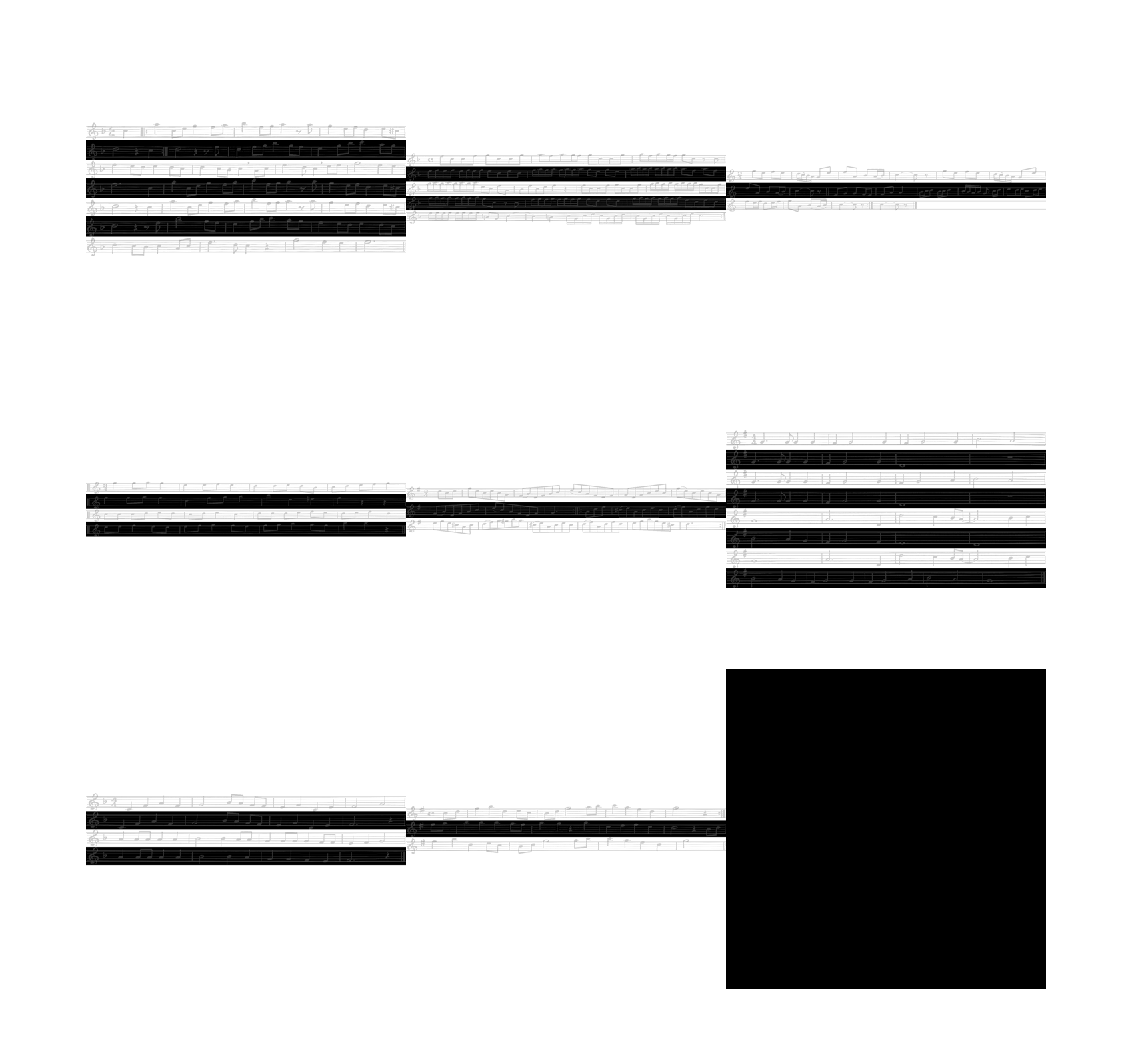





%imshowpair(preview(1).image, preview(2).image, 'montage');

previewCombined = [];
previewSize = 2048;
width = 3;
height = ceil(size(preview,1)/width);
for i=1:size(preview,1)
    previewCombined = cat(3, previewCombined, imresize(makeSquareSize(preview(i).image), [previewSize previewSize], 'bicubic'));
end

montage(previewCombined, 'Size', [height width]);

% polyfit (least squares) test
if false
    x = linspace(-10, 10, 20);
    slope = 1.5;
    intercept = -1;
    noiseAmplitude = 15;
    y = slope .* x + intercept + noiseAmplitude * rand(1, length(x));
    
    % Plot the training set of data.
    subplot(2, 1, 1);
    plot(x, y, 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    grid on;
    xlabel('X');
    ylabel('Y');
    title('Linear Fit');
    
    % Enlarge figure to full screen.
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
    % Give a name to the title bar.
    set(gcf, 'Name', 'Demo by ImageAnalyst', 'NumberTitle', 'Off') 
    
    % Do the regression with polyfit
    linearCoefficients = polyfit(x, y, 1)
    xFit = linspace(-15, 20, 50);
    yFit = polyval(linearCoefficients, xFit);
    hold on;
    plot(xFit, yFit, 'b.-', 'MarkerSize', 15, 'LineWidth', 1);
    legend('Training Set', 'Fit', 'Location', 'Northwest');
    hold off;
    grid off;
    subplot(1,1,1);
end

if false
    I = original;
    [I, background, hullMask] = extractnotesfromphoto(I);
    Iedges = edge(notes, 'sobel', 'nothinning', 'horizontal');
    
    %Ibw = (I < 0.9);
    %Ibw = notesEdges;
    Ibw = Iedges;
    Iskel = Ibw; %bwmorph(Ibw,'thin',inf);
    %%%%radon tranform horizontal
    [R xp] = radon(Ibw);
    [II JJ] = find(R >= (max(max(R)) * 0.75));
    imshow(Ibw); hold on;
    for k = 1 : size(II,1)
        R_i = (JJ(k) - 1) * 1;
        xp_i = xp(II(k));
        x_origin = size(Iskel,2) / 2 + (xp_i) * cos(R_i * pi / 180);
        y_origin = size(Iskel,1) / 2 - (xp_i) * sin(R_i * pi / 180);
        y1 = (y_origin - (1 - x_origin) * tan(((R_i) - 90) * pi / 180));
        ye = (y_origin - (size(Iskel,2) - x_origin) * tan(((R_i) - 90) * pi / 180));
        line([1 size(Iskel,2)], [y1 ye],'color','g');
    end
    
    % lines is a row of [A, B, C] line matrix
    %lines = [pointsToLineEquation(0,0, 5, 5)];
    %points = lineToBorderPoints(lines,size(I));
    %line(points([1,3]),points([2,4]), 'Color', 'Magenta');
    
    p1 = [0,0];
    p2 = [500,500];
    p3 = [200,0];
    p4 = [200,200];
    point = linlinintersect([p1; p2; p3; p4]);
    line(p1, p2, 'Color', 'Red');
    %line(p3, p4, 'Color', 'Blue');
    plot(point, 'Color', 'Magenta');
    hold off;
end

% Polyfit attempt
if false
    % Left edge polyfit
    leftSidePoints = sortrows(leftSidePoints, 2);
    x = leftSidePoints(:,1)';
    y = leftSidePoints(:,2)';
    linearCoefficients = polyfit(y, x, 1);
    f = polyval(linearCoefficients, y);
    figure;
    plot(y, x, y, f);
    
    imshow(imageBW);
    hold on;
    plot(f, y, 'Color', 'red');
    
    
    % Right edge polyfit
    rightSidePoints = sortrows(rightSidePoints, 2);
    x = rightSidePoints(:,1)';
    y = rightSidePoints(:,2)';
    linearCoefficients = polyfit(y, x, 1);
    f = polyval(linearCoefficients, y);
    plot(f, y, 'Color', 'magenta');
    hold off;
end

% Attempt to remove horizontal lines
if false
    verticals = imclose(loadimage("images/im1s.jpg"), strel('Line',20,90));
    horizontals = imclose(loadimage("images/im1s.jpg"), strel('Line',150,0));
    subtracted = 1-imsubtract(verticals, horizontals);
    result = imsubtract(notes, subtracted) > 0.01;
    imshow((1-notes).*result);
end


%stem(sum(notes<0.5,2));
%notes = imsharpen(notes,'Radius',1,'Amount',4);

% Noise removal
% notesw = wiener2(notes,[2 2]);
% imshow(notesw);
% notesm = medfilt2(notes);
% imshow(notesw);

% histeq(notes) enhances noise in white areas too much
% adapthisteq(notes); not much either
%notes_imadjust = medfilt2(notes_imadjust);
%imshow(notes_imadjust < 0.6);

%imhist(notes_imadjust);
%notesth = notes < 0.95; % threshold
%imshow(notesth);

% Using structuring elements to separate background from notes
if false
    notes = loadimage("images/im3c.jpg");
    %notesOpened = imopen(notes,strel('disk',16));
    %imshowpair(notesOpened, imsubtract(notes, notesOpened), 'montage');
    %imshowpair(imclose(notes, strel('disk',4)), imfill(notes,'holes'), 'montage');
    imshowpair(imclose(notes, strel('Disk',10)), imfill(notes,'holes'), 'montage');
    
    % Another similar attempt
    %imshow(imsubtract(imclose(notes, strel('Disk',10)), notes));
    background = imclose(notes, strel('Disk',10));
    extractedNotes = imsubtract(background, notes);
    result = imadjust(extractedNotes, [0.1, 0.5]);
    
    % Use sobel and morph. to extract pure paper edges
    paperEdge = edge(background, "sobel", 'nothinning');
    paperEdge = imerode(paperEdge, strel('Disk', 1, 0));
    paperEdge = imdilate(paperEdge, strel('Disk', 1, 0));
    imshow(paperEdge);
    
    %paperEdge = paperEdge.*hor;
    %imshow(imdilate(imerode(paperEdge, strel('Disk', 1, 4)), strel('Disk', 1, 4)));
end

% Emphasize notes
if false
    weakenedNotes = imdilate(notes, strel('Disk',4,8));
    strengthenedNotes = imerode(notes, strel('Disk',1,8));
    imshowpair(weakenedNotes, strengthenedNotes, 'montage');
end

% Another attempt at extracting notes
if false
    diff = imsubtract(notes, strengthenedNotes);
    mask = imdilate(diff, strel('Disk',4,4));
    binarymask = mask < 0.1;
    binarymask = 1-imfill(1-binarymask, 'holes');
    bg = notes.*binarymask;
    masked = 1-(imsubtract(notes, bg)+binarymask);
    
    cleaned = masked.*extractedNotes;
    imshow(cleaned);
end

% Blurry photo fix
if false
    notes = loadimage("images/im13c.jpg");
    notes = extractnotesfromphoto(notes);
    
    %Kaverage = filter2(fspecial('average',3), notes);
    %Kaverage = medfilt2(notes);
    denoised = notes;
    denoised = filter2(fspecial('unsharp'), denoised);
    %denoised = wiener2(denoised,[3 3]);
    imshow(denoised);
    
    %imshow(filterwithfourier(notes, 20));
    
    % sgolay did not help
    %k = 2;
    %windowSize = 5;
    %notesVsmooth = sgolayfilt(notes, k, windowSize, [], 1);
    %notesHsmooth = sgolayfilt(notes, k, windowSize, [], 2);
    %imshowpair(notesVsmooth, notesHsmooth, 'montage');
    
    %h = fspecial('unsharp');
    %I2 = imfilter(notes, h);
    %imshow(I2);
end

% Old tests for perspective correction 
if false
    plotLine = @(lS)plot([lS.origin.x, lS.end.x], [lS.origin.y, lS.end.y], 'LineWidth', 2, 'color', 'green');
    plotLineStart = @(lS)plot(lS.origin.x, lS.origin.y, 'x', 'LineWidth', 2, 'color', 'yellow');
    plotLineEnd = @(lS)plot(lS.end.x, lS.end.y, 'x', 'LineWidth', 2, 'color', 'red');
    
    loadedNotes = [];
    results = [];
    for i=1:size(imageFileNames, 2)
        original = imread(folder + imageFileNames(i));
        originalgray = im2double(rgb2gray(original));
        [notes, background, hullMask, notesBW] = extractnotesfromphoto(originalgray);
        
        %deblurWeight = imadjust(notes, [0.0 graythresh(notes)]);                    % only deblur bright regions (try to keep dark valleys untouched)
        %notes = deconvblind(notes, ones(5,5), 1, graythresh(notes), deblurWeight);  % apply single pass deblur
        
        loadedNotes = cat(3, loadedNotes, imresize(notes, [2048 2048], 'bicubic'));
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Perspective correction, straightening and normalization
        % Align staff lines horizontally
        [originalLines, orthoLines] = houghHorizontalAdjustment(notes);
        [notes, htform] = imwarpUsingLines(notes, originalLines, orthoLines);
        
        % Align staff lines vertically
        %[originalLines, alignedLines, debug] = staffSidesVerticalAdjustment(notesT);
        %[notesT, vtform] = imwarpUsingLines(notesT, originalLines, alignedLines);
        
        % Resample image by redoing transform on start/end points
    %     u = [];
    %     v = [];
    %     for k=1:size(originalLines)
    %         u = [u; originalLines(k).origin.x originalLines(k).end.x];
    %         v = [v; originalLines(k).origin.y originalLines(k).end.y];
    %     end
    %     
    %     [x, y] = transformPointsForward(htform, u, v);
    %     [x, y] = transformPointsForward(vtform, x, y);
    %     
    %     p = []; t = [];
    %     for k=1:size(x)
    %         p = [p; u(k) v(k)];
    %         t = [t; x(k) y(k)];
    %     end
    %     notes = 1-imwarp(1-notes, fitgeotrans(p, t, 'projective'));
        
        %notes = imcrop(notes, [pStart(1), pStart(2), pEnd(1)-pStart(1), pEnd(2)-pStart(2)]);
        
        %%%%%%% STAFF LINES V1 %%%%%%%%
        % Deblur picture and increase contrast so that lines can easier be
        % emphasized using structuring elements
    %     deblurWeight = imadjust(notes, [0.0 graythresh(notes)]);      % only deblur bright regions (try to keep dark valleys untouched)
    %     notes = deconvblind(notes, ones(5,5), 1, 1.0, deblurWeight);  % apply single pass deblur
    %     notes = imadjust(notes, [graythresh(notes) 1.0]);
    %     notes = imadjust(notes, [0.0 graythresh(notes)]);
    %     
    %     % Separate the lines
    %     segmentLength = size(notes,2)/4;
    %     notes = imerode(notes, strel('disk', 2, 4));
    %     notes = imdilate(notes, strel('line', segmentLength, 0));
    %     notes = imerode(notes, strel('line', segmentLength/2, 0));
        %%%%%% STAFF LINES END %%%%%%
        
        staffsInfo = staffLinesToBlocks(notes);
        bbox = staffsInfo.bboxesRegion;
        
        for k=1:staffsInfo.count
            bbox = staffsInfo.bboxes(k);
            notes(bbox.y1:bbox.y2, [bbox.x1, bbox.x2]) = 0;
            notes([bbox.y1,bbox.y2], bbox.x1:bbox.x2) = 0;
            notes(staffsInfo.labels == k) = 0;
        end
        
        %tform = fitgeotrans(points, targetPoints, 'projective');
        %notes = 1-imwarp(1-notes, tform);
            
        %%% BLOCK WISE LINE DETECTION
    %     blockSize = max(floor(size(notes)/16));
    %     result = blockprocstruct(notes, [blockSize, blockSize], @plotPerBlock);
    %     mask = zeros(size(notes));
    %     for k=1:size(result)
    %         lines = result(k).lines;
    %         for j=1:size(lines)
    %             mask(lines(j).origin.y, lines(j).origin.x) = 1;
    %             mask(lines(j).end.y, lines(j).end.x) = 1;    
    %         end
    %     end
    %     notes = mask;
        %%%%%%%%%%    
        
        
        %if maxLength > 0.0
        %    scaleFactor = 2048 / maxLength;
        %    notes = imresize(notes, [floor(2048*scaleFactor) floor(2048*scaleFactor)], 'bicubic');
        %end
        
        
        %notes = imcrop(notes, [minX, 0, (maxX-minX), size(notes, 2)]);
        
        % Make uniform size
        %diffx = max(0, size(notes,1)-size(notes,2));
        %diffy = max(0, size(notes,2)-size(notes,1));
        %notes = padarray(notes, [diffy diffx], 1);
        
        % Overlay black grid
        gridResolution = 32;
        [X Y] = meshgrid(1:size(notes,2), 1:size(notes, 1));
        %gridMask = or(mod(X, gridResolution)==0, mod(Y, gridResolution)==0);
       % notes(gridMask) = 0;
        
        results = cat(3, results, imresize(notes, [2048 2048], 'bicubic'));
    end
end


% function [result] = plotPerBlock(block)    
%     [originalLines, orthoLines] = houghHorizontalAdjustment(block.data, 2, "nopreprocess");
%     
%     maxAngleOffset = 5.0;
%     maxOffsetX = floor(block.blockSize(2)*0.05);
%     
%     blockx = block.location(2);
%     blocky = block.location(1);
%     
%     filteredLines = [];
%     for i=1:size(originalLines)
%         orgNew = originalLines(i);
%         absAngle = abs(abs(orgNew.theta)-90);
%         if absAngle < maxAngleOffset       
%             orgNew.origin.x = orgNew.origin.x + blockx;
%             orgNew.origin.y = orgNew.origin.y + blocky;
%             orgNew.end.x = orgNew.end.x + blockx;
%             orgNew.end.y = orgNew.end.y + blocky;
%             
%             p1 = orgNew.origin;
%             p2 = orgNew.end;
%             
%             % Only use lines that are close to the block edges
%             if abs(p1.x-blockx) <= maxOffsetX && abs(blockx+block.blockSize(2)-p2.x) <= maxOffsetX
%                 filteredLines = [filteredLines, orgNew];                
%             end
%         end
%     end
%     
%     result = struct;
%     result.lines = filteredLines;
%     result.image = block.data;
% end